**Demographic-Economic System Analysis:**

This script simulates the evolution of population age structure and analyzes the sustainability of the PAYG pension scheme.

clear; clc; close all;

Load Parameters:

% We fetch parameters from our setup file
P = get_parameters();

Check parameters (Optional display):

disp("Running simulation with Pension Replacement Rate (Beta): " + P.beta);

Running simulation with Pension Replacement Rate (Beta): 0.45


Setup Simulation:

Data from Austria: 

[https://www.statistik.at/statistiken/bevoelkerung-und-soziales/bevoelkerung/bevoelkerungsstand/bevoelkerung-nach-alter/geschlecht](https://www.statistik.at/statistiken/bevoelkerung-und-soziales/bevoelkerung/bevoelkerungsstand/bevoelkerung-nach-alter/geschlecht) 

% Initial Population Stocks (Scenario: Stable-ish start)
A_Y0 = 1766260; 
A_M0 = 5571276; 
A_O0 = 1859677;
Y0   = [A_Y0; A_M0; A_O0];

% Time Span (Years)
tspan = [0 150];

Run Solver:

% We use ode45 to solve the system defined in 'model_dynamics.mlx'
[t, Y] = ode45(@(t,y) model_dynamics(t, y, P), tspan, Y0);

Post-Processing:

% Reconstruct algebraic variables for analysis
Ay_hist = Y(:,1);
Am_hist = Y(:,2);
Ao_hist = Y(:,3);

% Avoid division by zero
Am_hist(Am_hist==0) = 1;

y_hist = Ay_hist ./ Am_hist;
o_hist = Ao_hist ./ Am_hist;

Recalculate Tax ($\tau$) and Fertility ($n$) history:

numerator   = P.alpha .* y_hist + P.beta .* o_hist;
denominator = 1 + numerator;
tau_hist    = numerator ./ denominator;

n_hist      = P.psi .* (1 - tau_hist);

Visualization:

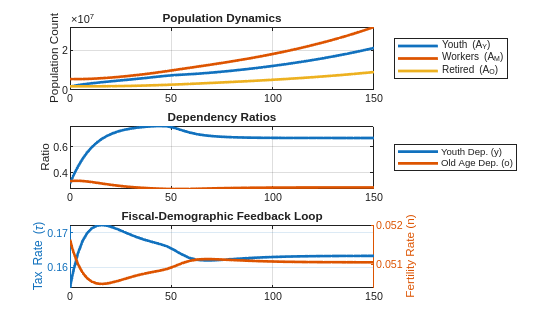

% Call the visualization function
visualize_results(t, Y, tau_hist, n_hist);